### Impact Energy: how hard does the docking contact hit?

Question this file answers: when the floating ABV runs into the fixed probe, how much energy does it carry, what peak force does that create, and does the contact surface get permanently dented? The peak force is the load for the Ansys structural analysis.

How the contact is modeled: the probe nose is treated as a rounded tip pressing into the drogue surface (Hertz contact, the standard model for two curved bodies touching). Behind the contact sits a spring that stands for how much the bracket, drogue and test stand flex. The softer that spring, the longer the hit lasts and the lower the peak force.

Aluminum question: we don’t yet know how much of the hardware will be aluminum. Swapping a PETG part for an aluminum part of the same shape makes it about twice as heavy, which raises the impact energy and the load on the PID controller. Section 2 shows that trend from 0% to 100% aluminum.

clear; clc; close all;

% ---- ABV and docking hardware ----
m_abv   = 12.7;                              % kg, abv_gnc config (not yet weighed)
V_hw    = (642.4 + 145.6 + 60.0) * 1e-6;     % m^3, drogue + bracket plate + clips (Fusion CAD)
growth  = 1.15;                              % x mass for bolts and brass inserts not in CAD
m_pid   = 2.35;                              % kg, most added mass the PID controller handles (thesis)
m_hw0 = 1.296

m_hw0 = 1.2960


% ---- Speeds ----
v_max   = 0.10;     % m/s, top of the SYS.10 docking band
v_fault = 0.125;    % m/s, NavAlert limit (DOCK.08): fastest the ABV should ever arrive

% ---- Contact geometry ----
R_contact = 0.0143; % m, probe nose radius (Fusion CAD). The real first touch is the probe's front
                    % edge on the drogue skirt; Dalton's Ansys contact results will replace this.

% ---- Structural flexibility behind the contact ----
k_struct = 3e5;     % N/m, BEST ESTIMATE: the 1/4 in PETG bracket plate bending under a load at its
                    % center works out to about 2-5 x 10^5 N/m by hand. Replace with Ansys
                    % (contact force / deflection) when available.

% ---- Materials (datasheets) ----
% OVERTURE PETG, TDS v5.2 (Dec 2025): density 1.30 g/cm^3, stiffness 2311 MPa,
% strength 47.9 MPa along layers / 45.7 MPa across layers. We use the weaker
% across-layer value x 0.8 for print defects and partial infill.
% Aluminum 6061-T6: standard handbook values (ASM / MatWeb).
mat   = ["PETG", "Aluminum 6061-T6"];
rho   = [1300, 2700];          % kg/m^3
E     = [2.311e9, 68.9e9];     % Pa
nu    = [0.38, 0.33];          % Poisson's ratio (PETG: typical value, not on the datasheet)
Sy    = [45.7e6*0.8, 276e6];   % Pa, strength used for the dent check
yfac  = 1.6;                   % a surface starts to dent when the peak contact pressure reaches 1.6 x strength

### 1) The three aluminum cases

0% = everything PETG (current plan). 50% = half the hardware volume aluminum, with an aluminum probe touching the PETG drogue. 100% = all aluminum, aluminum on aluminum. Margin above 1 means the contact springs back with no dent.

frac  = [0 0.5 1];
pairs = [1 1; 2 1; 2 2];       % [probe material, drogue material] for each case
Case  = ["0% aluminum (all PETG)"; "50% aluminum"; "100% aluminum"];
m_hw  = m_hw0 * ((1-frac)*rho(1) + frac*rho(2)) / rho(1);    % kg, same shapes, aluminum ~2.1x heavier
m_tot = m_abv + m_hw;

KE = zeros(3,2); F = zeros(3,2); p0 = zeros(3,2); marg = zeros(3,2);
spd = [v_max v_fault];
for k = 1:3
    for j = 1:2
        r = hertz_impact(m_tot(k), spd(j), R_contact, E(pairs(k,1)), nu(pairs(k,1)), Sy(pairs(k,1)), ...
                         E(pairs(k,2)), nu(pairs(k,2)), Sy(pairs(k,2)), yfac, k_struct);
        KE(k,j) = 0.5*m_tot(k)*spd(j)^2;  F(k,j) = r.F;  p0(k,j) = r.p0;  marg(k,j) = r.margin;
    end
end
PIDok = repmat({'OK'}, 3, 1);  PIDok(m_hw > m_pid) = {'OVER LIMIT'};
AluminumCases = table(Case, m_hw', PIDok, KE(:,1), KE(:,2), F(:,1), F(:,2), marg(:,1), marg(:,2), ...
    'VariableNames', {'Case', 'Hardware mass (kg)', 'PID limit 2.35 kg', 'Energy @0.10 (J)', ...
    'Energy @0.125 (J)', 'Peak force @0.10 (N)', 'Peak force @0.125 (N)', 'Dent margin @0.10', 'Dent margin @0.125'})

AluminumCases = 3×9 table
              Case              Hardware mass (kg)    PID limit 2.35 kg    Energy @0.10 (J)    Energy @0.125 (J)    Peak force @0.10 (N)    Peak force @0.125 (N)    Dent margin @0.10    Dent margin @0.125
    ________________________    __________________    _________________    ________________    _________________    ____________________    _____________________    _________________    __________________

    "0% aluminum (all PETG)"           1.296           {'OK'        }           0.06998             0.10934                194.02                  243.45                 0.84237                0.781      
    "50% aluminum"                    1.9938        


f_pid = (m_pid/m_hw0 - 1) * rho(1) / (rho(2) - rho(1));
fprintf('Going all-aluminum (same shapes) would put the hardware over the 2.35 kg PID limit.\n');

Going all-aluminum (same shapes) would put the hardware over the 2.35 kg PID limit.


fprintf('The limit is reached at about %.0f%% aluminum by volume.\n', 100*f_pid);

The limit is reached at about 76% aluminum by volume.


### 2) Energy and force as the aluminum share grows

f_sweep = linspace(0, 1, 51);
m_sw  = m_hw0 * ((1-f_sweep)*rho(1) + f_sweep*rho(2)) / rho(1);
KE_sw = 0.5 * (m_abv + m_sw) .* [v_max; v_fault].^2;      % J, rows = speed
F_sw  = zeros(2, numel(f_sweep));
for j = 1:2
    for i = 1:numel(f_sweep)
        F_sw(j,i) = hertz_impact(m_abv + m_sw(i), spd(j), R_contact, E(1), nu(1), Sy(1), E(1), nu(1), Sy(1), yfac, k_struct).F;
    end
end
fprintf('From 0%% to 100%% aluminum, impact energy at 0.10 m/s rises from %.3f J to %.3f J (+%.0f%%).\n', ...
    KE_sw(1,1), KE_sw(1,end), 100*(KE_sw(1,end)/KE_sw(1,1) - 1));

From 0% to 100% aluminum, impact energy at 0.10 m/s rises from 0.070 J to 0.077 J (+10%).


### 3) Sensitivity to how much the structure flexes

k_list = [1e4 1e5 3e5 1e6 1e7 Inf];
Fk = zeros(3, numel(k_list)); Mk = Fk;
for k = 1:3
    for q = 1:numel(k_list)
        r = hertz_impact(m_tot(k), v_max, R_contact, E(pairs(k,1)), nu(pairs(k,1)), Sy(pairs(k,1)), ...
                         E(pairs(k,2)), nu(pairs(k,2)), Sy(pairs(k,2)), yfac, k_list(q));
        Fk(k,q) = r.F;  Mk(k,q) = r.margin;
    end
end
Stiffness = compose('%.0e N/m', k_list'); Stiffness(end) = {'Rigid (upper bound)'};
StiffnessSensitivity = table(Stiffness, Fk(1,:)', Mk(1,:)', Fk(2,:)', Mk(2,:)', Fk(3,:)', Mk(3,:)', ...
    'VariableNames', {'Structure stiffness', 'Force, PETG (N)', 'Margin, PETG', ...
    'Force, 50% Al (N)', 'Margin, 50% Al', 'Force, 100% Al (N)', 'Margin, 100% Al'})

StiffnessSensitivity = 6×7 table
      Structure stiffness      Force, PETG (N)    Margin, PETG    Force, 50% Al (N)    Margin, 50% Al    Force, 100% Al (N)    Margin, 100% Al
    _______________________    _______________    ____________    _________________    ______________    __________________    _______________

    {'1e+04 N/m'          }        37.287            1.4597            38.251             0.93288              39.219               1.1579    
    {'1e+05 N/m'          }        115.69            1.0008            119.49             0.63816              123.77              0.78942    
    {'3e+05 N/m'          }        194.02           0.84237            202.66             0.53512              213.61              0.65812    
    {'1e+06 N


k_ok = max_stiffness(m_tot(1), v_fault, R_contact, E(1), nu(1), Sy(1), yfac);
fprintf('For an all-PETG contact to stay dent-free at 0.125 m/s, the structure must be no stiffer than %.1e N/m.\n', k_ok);

For an all-PETG contact to stay dent-free at 0.125 m/s, the structure must be no stiffer than 6.3e+04 N/m.


### 4) Loads for the Ansys analysis

r  = hertz_impact(m_tot(1), v_max,   R_contact, E(1), nu(1), Sy(1), E(1), nu(1), Sy(1), yfac, k_struct);
r2 = hertz_impact(m_tot(1), v_fault, R_contact, E(1), nu(1), Sy(1), E(1), nu(1), Sy(1), yfac, k_struct);
Load = ["Normal docking (0.10 m/s)"; "Fault (0.125 m/s)"];
AnsysLoads = table(Load, F(1,:)', [r.a; r2.a]*1e3, ...
    'VariableNames', {'Load case (all PETG)', 'Peak force (N)', 'Contact patch radius (mm)'})

AnsysLoads = 2×3 table
       Load case (all PETG)        Peak force (N)    Contact patch radius (mm)
    ___________________________    ______________    _________________________

    "Normal docking (0.10 m/s)"        194.02                  1.155          
    "Fault (0.125 m/s)"                243.45                 1.2458          


fprintf('Apply the peak force at the probe nose and react it through the mount. The hit lasts about %.0f ms;\n', r.t_c*1e3);

Apply the peak force at the probe nose and react it through the mount. The hit lasts about 22 ms;


fprintf('if the bracket''s lowest natural frequency is above ~%.0f Hz, a static Ansys run is fine.\n', 3/r.t_c);

if the bracket's lowest natural frequency is above ~135 Hz, a static Ansys run is fine.


fprintf('Cross-check: Dalton''s transient Ansys showed 24 MPa peak stress and 8 MPa contact pressure.\n');

Cross-check: Dalton's transient Ansys showed 24 MPa peak stress and 8 MPa contact pressure.


fprintf('This file predicts %.0f MPa peak contact pressure; the difference is the rounded-tip model.\n', r.p0/1e6);

This file predicts 69 MPa peak contact pressure; the difference is the rounded-tip model.


### Plots

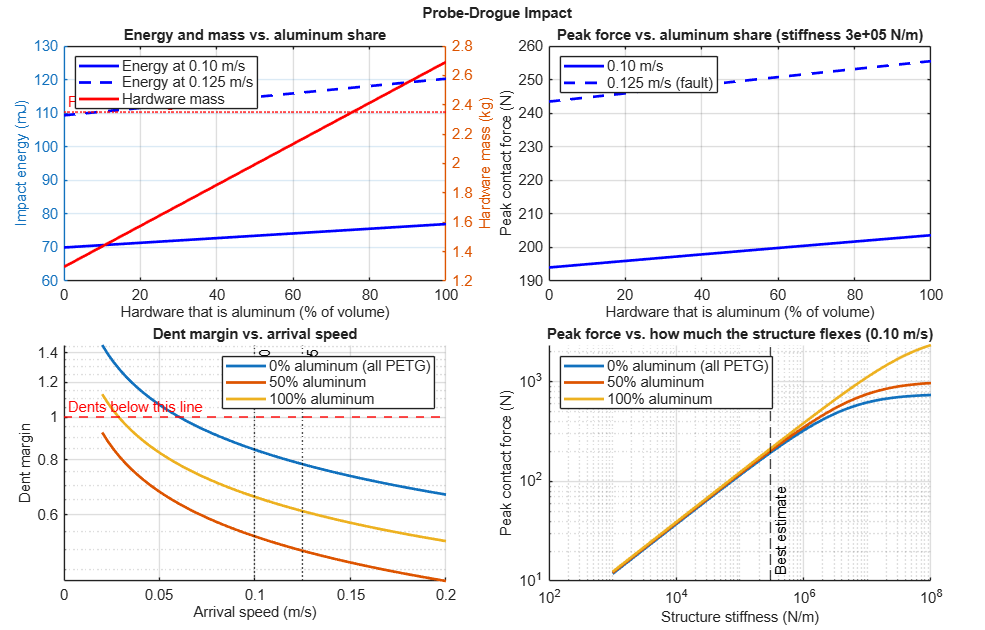

fig = figure('Name', 'Impact Energy', 'Position', [60 60 1250 800]);
theme(fig, 'light');
tl = tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
yyaxis left;  plot(100*f_sweep, KE_sw(1,:)*1e3, 'b-', 'LineWidth', 2); hold on;
              plot(100*f_sweep, KE_sw(2,:)*1e3, 'b--', 'LineWidth', 2);
ylabel('Impact energy (mJ)');
yyaxis right; plot(100*f_sweep, m_sw, 'r-', 'LineWidth', 2);
yline(m_pid, 'r:', 'PID limit 2.35 kg', 'LineWidth', 1.5, 'LabelHorizontalAlignment', 'left', 'HandleVisibility', 'off');
ylabel('Hardware mass (kg)');
xlabel('Hardware that is aluminum (% of volume)');
title('Energy and mass vs. aluminum share');
legend('Energy at 0.10 m/s', 'Energy at 0.125 m/s', 'Hardware mass', 'Location', 'northwest'); grid on;

nexttile;
plot(100*f_sweep, F_sw(1,:), 'b-', 'LineWidth', 2); hold on;
plot(100*f_sweep, F_sw(2,:), 'b--', 'LineWidth', 2);
xlabel('Hardware that is aluminum (% of volume)'); ylabel('Peak contact force (N)');
title(sprintf('Peak force vs. aluminum share (stiffness %.0e N/m)', k_struct));
legend('0.10 m/s', '0.125 m/s (fault)', 'Location', 'northwest'); grid on;

nexttile; hold on;
v_sw = linspace(0.02, 0.2, 60); cols = lines(3);
for k = 1:3
    mv = arrayfun(@(v) hertz_impact(m_tot(k), v, R_contact, E(pairs(k,1)), nu(pairs(k,1)), Sy(pairs(k,1)), ...
         E(pairs(k,2)), nu(pairs(k,2)), Sy(pairs(k,2)), yfac, k_struct).margin, v_sw);
    plot(v_sw, mv, '-', 'Color', cols(k,:), 'LineWidth', 2, 'DisplayName', Case(k));
end
yline(1, 'r--', 'Dents below this line', 'LineWidth', 1.5, 'HandleVisibility', 'off', 'LabelHorizontalAlignment', 'left');
xline(v_max, 'k:', '0.10', 'HandleVisibility', 'off'); xline(v_fault, 'k:', '0.125', 'HandleVisibility', 'off');
set(gca, 'YScale', 'log');
xlabel('Arrival speed (m/s)'); ylabel('Dent margin');
title('Dent margin vs. arrival speed'); legend('Location', 'northeast'); grid on;

nexttile; hold on;
k_fine = logspace(3, 8, 50);
for k = 1:3
    Fk2 = arrayfun(@(kk) hertz_impact(m_tot(k), v_max, R_contact, E(pairs(k,1)), nu(pairs(k,1)), Sy(pairs(k,1)), ...
          E(pairs(k,2)), nu(pairs(k,2)), Sy(pairs(k,2)), yfac, kk).F, k_fine);
    plot(k_fine, Fk2, '-', 'Color', cols(k,:), 'LineWidth', 2, 'DisplayName', Case(k));
end
xline(k_struct, 'k--', 'Best estimate', 'HandleVisibility', 'off', 'LabelVerticalAlignment', 'bottom');
set(gca, 'XScale', 'log', 'YScale', 'log');
xlabel('Structure stiffness (N/m)'); ylabel('Peak contact force (N)');
title('Peak force vs. how much the structure flexes (0.10 m/s)'); legend('Location', 'northwest'); grid on;

title(tl, 'Probe-Drogue Impact', 'FontWeight', 'bold');
fontsize(fig, 11, 'points');

### Local functions

function r = hertz_impact(m, v, R, E1, nu1, Sy1, E2, nu2, Sy2, yf, k_s)
% Rounded tip (radius R, part 1) hitting a surface (part 2), with a spring k_s behind it.
% Peak force comes from: kinetic energy = energy stored in the contact + energy stored in the spring.
Estar = 1 / ((1-nu1^2)/E1 + (1-nu2^2)/E2);
KE = 0.5*m*v^2;
dH = @(F) (3*F/(4*Estar*sqrt(R)))^(2/3);
if isinf(k_s), energy = @(F) 0.4*F*dH(F);
else,          energy = @(F) 0.4*F*dH(F) + F^2/(2*k_s);
end
lo = 0; hi = 1;
while energy(hi) < KE, hi = 2*hi; end
for it = 1:200
    mid = 0.5*(lo + hi);
    if energy(mid) < KE, lo = mid; else, hi = mid; end
end
r.F = 0.5*(lo + hi);
r.dent = dH(r.F);
if isinf(k_s), x = r.dent; else, x = r.dent + r.F/k_s; end
r.a  = sqrt(R*r.dent);                  % contact patch radius
r.p0 = 3*r.F / (2*pi*r.a^2);            % peak contact pressure
r.t_c = 3 * x / v;                      % approximate contact duration
r.margin = min(yf*Sy1, yf*Sy2) / r.p0;
end

function k_max = max_stiffness(m, v, R, E, nu, Sy, yf)
% Stiffest structure that keeps a same-material contact dent-free.
if hertz_impact(m, v, R, E, nu, Sy, E, nu, Sy, yf, Inf).margin >= 1, k_max = Inf; return; end
lo = 1; hi = 1e12;
for it = 1:100
    mid = sqrt(lo*hi);
    if hertz_impact(m, v, R, E, nu, Sy, E, nu, Sy, yf, mid).margin >= 1, lo = mid; else, hi = mid; end
end
k_max = lo;
end